filtdata = csvread('Lavpass.csv',1,0);
fd=filtdata(:,1);
Hd=filtdata(:,2);
[f_cd, ~] = min(abs(Hd) + 3);

L=0.1;
C=470*10.^(-6);
w=1:0.5:8000

w = 1.0e+03 *

    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245    0.0250    0.0255


H_Upper=1;
H_lower=sqrt((1+(w.^2*L*C).^2))

H_lower = 1.0e+03 *

    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


H=H_Upper./H_lower

H =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9998    0.9998    0.9998    0.9998    0.9998    0.9997    0.9997    0.9997    0.9997    0.9996    0.9996    0.9996    0.9995


f=w./(2*pi)

f = 1.0e+03 *

    0.0002    0.0002    0.0003    0.0004    0.0005    0.0006    0.0006    0.0007    0.0008    0.0009    0.0010    0.0010    0.0011    0.0012    0.0013    0.0014    0.0014    0.0015    0.0016    0.0017    0.0018    0.0018    0.0019    0.0020    0.0021    0.0021    0.0022    0.0023    0.0024    0.0025    0.0025    0.0026    0.0027    0.0028    0.0029    0.0029    0.0030    0.0031    0.0032    0.0033    0.0033    0.0034    0.0035    0.0036    0.0037    0.0037    0.0038    0.0039    0.0040    0.0041



[fc, index] = min(abs(mag2db(H) + 3));

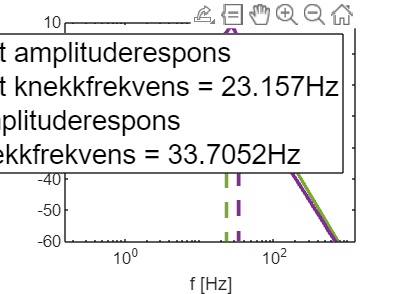

figure;
semilogx(f,mag2db(H),'Color',[0.4660 0.6740 0.1880],'LineWidth',2);
hold on;
plot([min(f) f(index) f(index)], [-3 -3 -70], '--','Color',[0.4660 0.6740 0.1880],'LineWidth',2);
semilogx(fd,Hd,'Color',[0.4940 0.1840 0.5560],'LineWidth',2);
plot([min(f) fd(47) fd(47)], [f_cd f_cd -70], '--','Color',[0.4940 0.1840 0.5560],'LineWidth',2);
plot(f(index),mag2db(H(index)),'.','color',[0.4660 0.6740 0.1880],'MarkerSize',30);
plot(fd(47),f_cd,'.','color',[0.4940 0.1840 0.5560],'MarkerSize',30);
ylabel("[dB]"); ylim([-60 10])
xlabel("f [Hz]"); xlim([0 max(f)]);
legend("Forventet amplituderespons","Forventet knekkfrekvens = "+f(index)+"Hz","Reell Amplituderespons","Reell knekkfrekvens = "+fd(47)+"Hz",'fontsize',15)
set(get(gca,'ylabel'),'rotation',0);